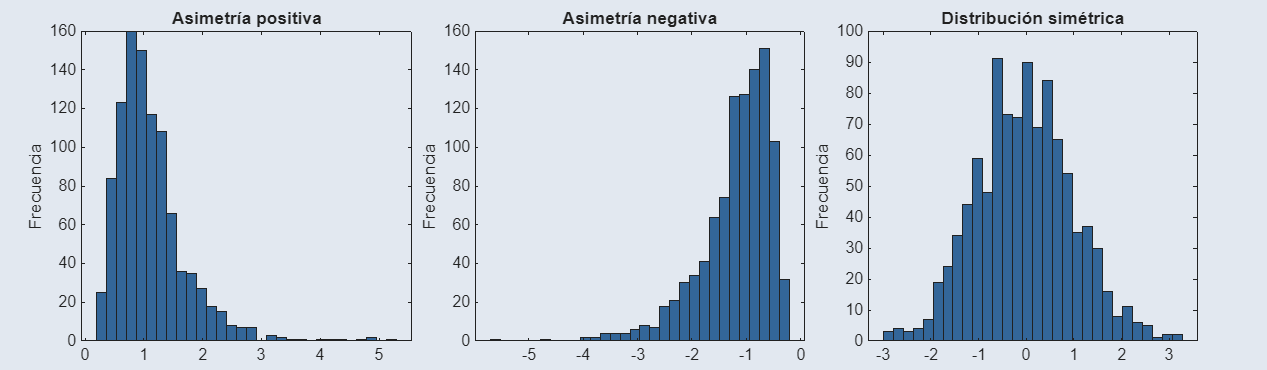

%% Asimetría — 3 casos en una sola imagen
clear
clc

rng(1);

data_pos = lognrnd(0, 0.5, 1000, 1);
data_neg = -lognrnd(0, 0.5, 1000, 1);
data_sym = normrnd(0, 1, 1000, 1);

color_fondo = [226 232 240] / 255;

figure('Color', color_fondo, 'Position', [100 100 1200 350]);
t = tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
histogram(data_pos, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Asimetría positiva'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

nexttile;
histogram(data_neg, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Asimetría negativa'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

nexttile;
histogram(data_sym, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Distribución simétrica'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

exportgraphics(t, 'asimetria_casos.png', 'Resolution', 150);

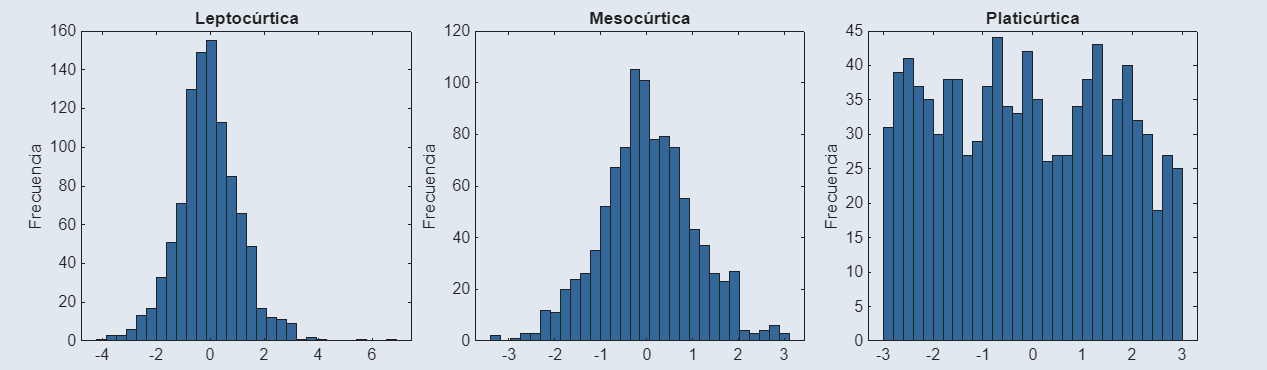


%% Curtosis — 3 casos en una sola imagen
clear
clc

rng(2);

data_lepto = trnd(7, 1000, 1);
data_meso = normrnd(0, 1, 1000, 1);
data_plati = -3 + 6*rand(1000, 1);

color_fondo = [226 232 240] / 255;

figure('Color', color_fondo, 'Position', [100 100 1200 350]);
t = tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
histogram(data_lepto, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Leptocúrtica'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

nexttile;
histogram(data_meso, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Mesocúrtica'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

nexttile;
histogram(data_plati, 30, 'FaceColor', [0.2 0.4 0.6], 'FaceAlpha', 1);
title('Platicúrtica'); ylabel('Frecuencia');
set(gca, 'Color', color_fondo);

exportgraphics(t, 'curtosis_casos.png', 'Resolution', 150);